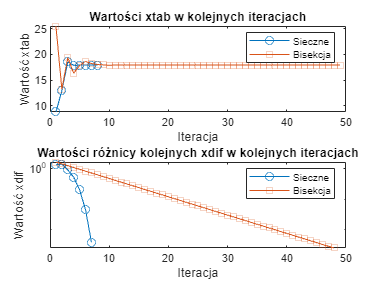

a = 1;
b = 50;
ytolerance = 1e-12;
max_iterations = 100;
fun = @rocket_velocity;
[time_secant, ysolution_secant, iterations_secant, xtab_secant, xdif_secant] = secant_method(a, b, max_iterations, ytolerance, fun);
[time_bisection, ysolution_bisection, iterations_bisection, xtab_bisection, xdif_bisection] = bisection_method(a, b, max_iterations, ytolerance, fun);

% Wykresy
figure;

% Wykres dla xtab
subplot(2, 1, 1);
plot(1:iterations_secant, xtab_secant, '-o', 'DisplayName', 'Sieczne');
hold on;
plot(1:iterations_bisection, xtab_bisection, '-s', 'DisplayName', 'Bisekcja');
hold off;
xlabel('Iteracja');
ylabel('Wartość xtab');
title('Wartości xtab w kolejnych iteracjach');
legend;

% Wykres dla xdif
subplot(2, 1, 2);
semilogy(1:(iterations_secant-1), xdif_secant, '-o', 'DisplayName', 'Sieczne');
hold on;
semilogy(1:(iterations_bisection-1), xdif_bisection, '-s', 'DisplayName', 'Bisekcja');
hold off;
xlabel('Iteracja');
ylabel('Wartość xdif');
title('Wartości różnicy kolejnych xdif w kolejnych iteracjach');
legend;

function [xsolution, ysolution, iterations, xtab, xdif] = secant_method(a, b, max_iterations, ytolerance, fun)
% a - lewa granica przedziału poszukiwań miejsca zerowego (x0=a)
% b - prawa granica przedziału poszukiwań miejsca zerowego (x1=b)
% max_iterations - maksymalna liczba iteracji działania metody siecznych
% ytolerance - wartość abs(fun(xsolution)) powinna być mniejsza niż ytolerance
% fun - nazwa funkcji, której miejsce zerowe będzie wyznaczane
%
% xsolution - obliczone miejsce zerowe
% ysolution - wartość fun(xsolution)
% iterations - liczba iteracji wykonana w celu wyznaczenia xsolution
% xtab - wektor z kolejnymi kandydatami na miejsce zerowe, począwszy od x2
% xdiff - wektor wartości bezwzględnych z różnic pomiędzy i-tym oraz (i+1)-ym elementem wektora xtab; xdiff(1) = abs(xtab(2)-xtab(1));
    
xsolution = [];
ysolution = [];
iterations = [];
xtab = [];
xdif = [];

for i = 1:max_iterations
    y0 = fun(a);
    y1 = fun(b);
    x = b - y1 * (b - a) / (y1 - y0);
    y = fun(x);
    xsolution = x;
    ysolution = y;
    iterations = i;
    xtab(i,1) = x;
    if i > 1
        xdif(i-1,1) = abs(xtab(i,1) - xtab(i-1,1));
    end
    if abs(y) < ytolerance
        break;
    end
    a = b;
    b = x;
    end
end

function [xsolution, ysolution, iterations, xtab, xdif] = bisection_method(a, b, max_iterations, ytolerance, fun)
% a - lewa granica przedziału poszukiwań miejsca zerowego
% b - prawa granica przedziału poszukiwań miejsca zerowego
% max_iterations - maksymalna liczba iteracji działania metody bisekcji
% ytolerance - wartość abs(fun(xsolution)) powinna być mniejsza niż ytolerance
% fun - nazwa funkcji, której miejsce zerowe będzie wyznaczane
%
% xsolution - obliczone miejsce zerowe
% ysolution - wartość fun(xsolution)
% iterations - liczba iteracji wykonana w celu wyznaczenia xsolution
% xtab - wektor z kolejnymi kandydatami na miejsce zerowe, począwszy od xtab(1)= (a+b)/2
% xdiff - wektor wartości bezwzględnych z różnic pomiędzy i-tym oraz (i+1)-ym elementem wektora xtab; xdiff(1) = abs(xtab(2)-xtab(1));
    
xsolution = [];
ysolution = [];
iterations = [];
xtab = [];
xdif = [];
if fun(a) * fun(b) >= 0
    error('Funkcja nie zmienia znaku na krańcach przedziału. Metoda bisekcji nie może zostać zastosowana.');
end
    
for i = 1:max_iterations
    x = (a + b) / 2;
    y = fun(x);
    xsolution = x;
    ysolution = y;
    iterations = i;
    xtab(i,1) = x;
    if i > 1
        xdif(i-1,1) = abs(xtab(i,1) - xtab(i-1,1));
    end
    if abs(y) < ytolerance
        break;
    end
    if fun(a) * y < 0
        b = x;
    else
        a = x;
    end
end
end

function velocity_delta = rocket_velocity(t)
% velocity_delta - różnica pomiędzy prędkością rakiety w czasie t oraz zadaną prędkością M
% t - czas od rozpoczęcia lotu rakiety dla którego ma być wyznaczona prędkość rakiety
M = 750; % [m/s]
u = 2000; %[m/s]
q = 2700; %[kg/s]
m0 = 150000; %[kg]
g = 1.622; %[m/s/s]

if t <= 0
    error("Czas musi byc wiekszy od 0.");
end

v = u*log(m0/(m0-q*t)) - g*t;

velocity_delta = v - M;

end


